## Example 2-10

A 1-kVA, 230/115-V, 60-Hz single-phase transformer has 850 turns on the primary winding and 425 turns on the secondary winding. The magnetization curve for this transformer is shown in Figure 2-45. 

(a) Calculate and plot the magnetization current of this transformer when it is run 

at 230 V on a 60-Hz power source. What is the rms value of the magnetization current? 

(b) Calculate and plot the magnetization current of this transformer when it is run at 

230 V on a 50-Hz power source. What is the rms value of the magnetization cur

rent? How does this current compare to the magnetization current at 60 Hz?

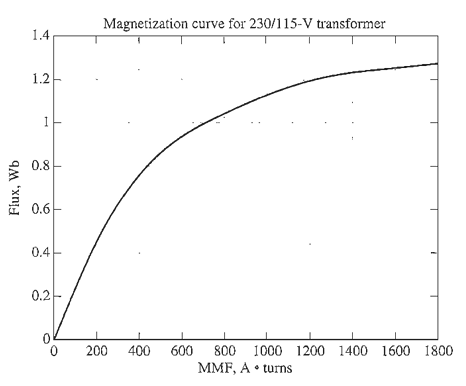

% M-file: mag_current.m 
% M-file to calculate and plot the magnetization 
% current of a 230/115 transformer operating at 
% 230 volts and 50/60 Hz . This program also 
% calculat es t he rms value of the mag. current. 
% Load the magnetization curve. It is in two 
% columns, with the first column being rumf and 
% the second column being flux.

load mag_curve_1.dat;
mmf_data = mag_curve_1(:, 1);
flux_data = mag_curve_1(:, 2);

% Initialize value
VM = 325; % Maximum voltage (V) 
NP = 850; % Primary turns

% Calculate angular velocity for 60 Hz
freq = 60; % Freq (Hz)
w = 2 * pi * freq;

% Calculate flux versus time
time = 0 : 1/3000 : 1/30 ; % 0 to 1/30 sec
flux = -VM / (w * NP) * cos(w .* time);

% Calculate the muf corresponding to a given flux 
% using the flux's interpolation function .
mmf = interp1(flux_data, mmf_data, flux);
% Calculate the magnetization current 
im = mmf / NP;
% Calculate the rms value of the current
irms = sqrt(sum(im .^ 2) / length(im));
disp(['The rms current at 60 Hz is ', num2str(irms)]) ;

The rms current at 60 Hz is 0.4894



% Plot the magnetization current
figure(1);
subplot(2, 1, 1); 
plot(time, im);
title ('\bfMagnetization Current at 60 Hz');
xlabel ('\bfTime (s)') ;
ylabel ('\bf\itI_(m) \rm(A)') ;
axis([0 0.04 -2 2]);
grid on;

% Calculate angular velocity for 50 hz
freq = 50; % Freq (Hz)
w = 2 * pi * freq;
% Calcu late flux versus time 
time = 0 : 1/2500 : 1/25; % 0 to 1/25 sec
flux = -VM / (w * NP) * cos(w .* time);
% Calculate the mm = corresponding to a given flux
% using the flux's interpolation function . 
mmf = interp1(flux_data, mmf_data, flux);
% Calculate the magnetization current 
im = mmf / NP;
% Calculate the rms value of the current
irms = sqrt (sum(im .^ 2) / length(im));
disp ( ['The rms current at 50 Hz is ', num2str(irms)]);

The rms current at 50 Hz is 0.79252


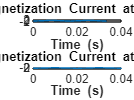


% Plot the magnetization current
subplot (2, 1, 2);
plot (time, im);
title ('\bfMagnetization Current at 50 Hz');
xlabel ('\bfTime (s)') ;
ylabel ('\bf\itI_(m) \rm(A)') ;
axis([0 0.04 -2 2]);
grid on;